% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 15);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["trial", "active_trials", "contrast_left", "contrast_right", "stim_onset", "gocue_time", "response_type", "response_time", "feedback_time", "feedback_type", "reaction_time", "reaction_type", "mouse", "session_date", "session_id"];
opts.VariableTypes = ["double", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "categorical", "datetime", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["active_trials", "mouse"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "session_date", "InputFormat", "yyyy-MM-dd");
opts = setvaropts(opts, "session_id", "TrimNonNumeric", true);
opts = setvaropts(opts, "session_id", "ThousandsSeparator", ",");

% Import the data
steinmetz_winter20172 = readtable("/home/ben/ibots/matlab-workshop-1/iBOTS-Intro-to-Matlab-for-Neuroscientists-main/day1/data/steinmetz_winter2017.csv", opts);

% Clear temporary variables
clear opts

% Display results
steinmetz_winter20172

steinmetz_winter20172 = 7906×15 table
    trial    active_trials    contrast_left    contrast_right    stim_onset    gocue_time    response_type    response_time    feedback_time    feedback_type    reaction_time    reaction_type     mouse     session_date    session_id
    _____    _____________    _____________    ______________    __________    __________    _____________    _____________    _____________    _____________    _____________    _____________    _______    ____________    ______

mouse_grouping_count = groupsummary(steinmetz_winter20172, "mouse")

mouse_grouping_count = 5×2 table
      mouse      GroupCount
    _________    __________

    Forssmann       1485   
    Lederberg       2902   
    Richards        1677   
    Tatum           1389   
    Theiler          453   



mouse_grouping_count.mouse

ans = 5×1 categorical array
     Forssmann 
     Lederberg 
     Richards 
     Tatum 
     Theiler 


my_table= groupsummary(steinmetz_winter20172, "mouse", "mean", "response_time")

my_table = 5×3 table
      mouse      GroupCount    mean_response_time
    _________    __________    __________________

    Forssmann       1485             1.4706      
    Lederberg       2902             1.1438      
    Richards        1677             1.3583      
    Tatum           1389             1.3377      
    Theiler          453             1.3388      



mean(my_table.mean_response_time)

ans = 1.3298

mean(steinmetz_winter20172.response_time, "omitmissing")

ans = 1.2929

## Review

data1 = readtable("data/steinmetz_summer2017.csv");

data1(1:20, "contrast_left")

ans = 20×1 table
    contrast_left
    _____________

           0     
          50     
           0     
           0     
           0     
           0     
          50     
           0     
          50     
           0     
         100     
          25     
           0     
          25     
           0     
           0     


mean(data1.response_time, "omitmissing")

ans = 1.6014

range(data.response_time, "omitmissing")

ans = 2.2342

table_mice = groupsummary(data1, "mouse")

table_mice = 2×2 table
      mouse      GroupCount
    _________    __________

    {'Hench'}       1851   
    {'Moniz'}        896   


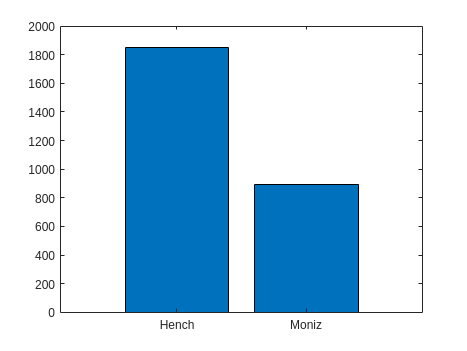


bar(table_mice.mouse, table_mice.GroupCount)

data2 = readtable("data/steinmetz_winter2016.csv");
data3 = readtable("data/steinmetz_winter2017.csv");

data = [data1; data2; data3];

table_mice = groupsummary(data, "mouse")

table_mice = 10×2 table
        mouse        GroupCount
    _____________    __________

    {'Cori'     }       1143   
    {'Forssmann'}       1485   
    {'Hench'    }       1851   
    {'Lederberg'}       2902   
    {'Moniz'    }        896   
    {'Muller'   }       1112   
    {'Radnitz'  }       1512   
    {'Richards' }       1677   
    {'Tatum'    }       1389   
    {'Theiler'  }        453   


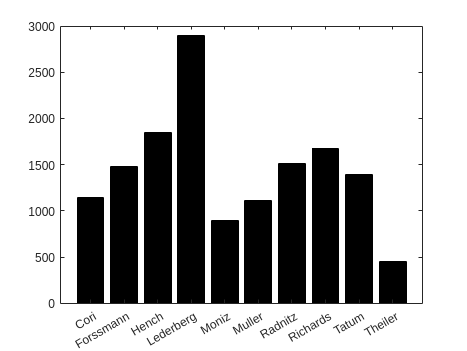


bar(table_mice.mouse, table_mice.GroupCount, "black")

sorted_table = sortrows(table_mice, "GroupCount")

sorted_table = 10×2 table
        mouse        GroupCount
    _____________    __________

    {'Theiler'  }        453   
    {'Moniz'    }        896   
    {'Muller'   }       1112   
    {'Cori'     }       1143   
    {'Tatum'    }       1389   
    {'Forssmann'}       1485   
    {'Radnitz'  }       1512   
    {'Richards' }       1677   
    {'Hench'    }       1851   
    {'Lederberg'}       2902   


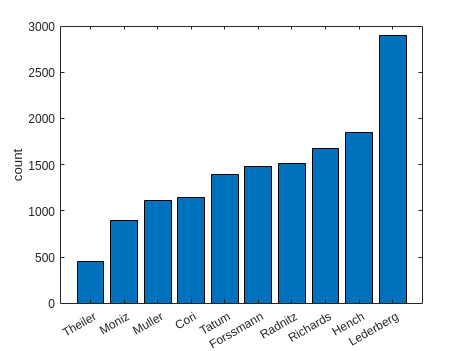

bar(sorted_table.mouse, sorted_table.GroupCount)
ylabel("count")